# Sammensatte Komponenter

Basic kølekreds

noget andet

clc; clear;

CP = py.importlib.import_module("CoolProp.CoolProp");

kelvin = 273.15;

% Coolant fluid
fluid = "R134a";
qmr = 0.05;





# Kompressor

format longG
% Initial states in position 1 (before compressor)
x1 = 1; % quality
T1 = 5 + kelvin;

h1 = CP.PropsSI("H","T",T1,"Q",x1,fluid);
s1 = CP.PropsSI("S","T",T1,"Q",x1,fluid);
p1 = CP.PropsSI("P","T",T1,"Q",x1,fluid);

dens = CP.PropsSI("D","T",T1,"Q",x1,fluid);
v1 = 1/dens;

s2 = s1;

% Compressor details
V_sv = 50/1e6;
qV = V_sv * 50;
qmr = qV * dens

qmr =         0.0428271437253645


# Kondensator

Vi kigger på 3 stadier i kondensatoren

- Desuperheating 2-3

- Kondensering 3-4

- Underkøling 4-5

% We assume a condensation temperature of 35
T_kond = 35 + kelvin;
subcool = 5;
x_kond = 0;

% Saturation pressure
p_sat = CP.PropsSI("P","T",T_kond,"Q",x_kond,fluid);

% Pressure during condensation is constant (idealization)
p2 = p_sat;
p3 = p_sat;
p4 = p_sat; 
p5 = p_sat; 

% Temperatures
T2 = CP.PropsSI("T","S",s2,"P",p2,fluid)

T2 =            311.46243579293


T3 = T_kond

T3 =                     308.15


T4 = T_kond

T4 =                     308.15


T5 = T_kond - subcool

T5 =                     303.15



% Enthalpies
h2 = CP.PropsSI("H","P",p2,"T",T2,fluid)

h2 =           420805.283134601


h3 = CP.PropsSI("H","P",p3,"Q",x1,fluid)

h3 =           417188.643325733


h4 = CP.PropsSI("H","P",p4,"Q",x_kond,fluid)

h4 =           249006.651855519


h5 = CP.PropsSI("H","P",p5,"T",T5,fluid)

h5 =           241718.878739714



% Desuperheating LMTD


% Energy flows
% qmr = 0.04;
Q_komp      = qmr * (h2 - h1)

Q_komp =           827.120312675859


Q_desuper   = - qmr * (h3 - h2)

Q_desuper =            154.89035289727


Q_kond      = - qmr * (h4 - h3)

Q_kond =            7202.7543207129


Q_subcool   = - qmr * (h5 - h4)

Q_subcool =           312.114506668405


# Desuperheating

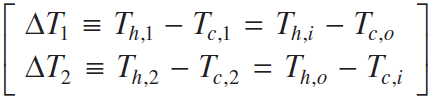

% Air for condensation
amb_fluid = "Air";
T_ambient = 25 + kelvin;
P_amb = 101325,

P_amb =       101325


cp_air = CP.PropsSI("C","P",P_amb,"T",T_ambient,amb_fluid);
dens_air = CP.PropsSI("D","P",P_amb,"T",T_ambient,amb_fluid);
thermkon_air = CP.PropsSI("L","P",P_amb,"T",T_ambient,amb_fluid);

syms T_air_out A_desuper %qmr_air
qmr_air = 0.4; % Assumed

DT1_desuper = abs(T2 - T_air_out);
DT2_desuper = abs(T3 - T_ambient);

LMTD_desuper = (DT2_desuper - DT1_desuper)/(log(DT2_desuper/DT1_desuper));

% Condensator Desuper
% A_desuper = 0.2 * 0.4;
U_desuper = 20;

Q_lmtd_desuper = Q_desuper == U_desuper*A_desuper*LMTD_desuper;
Q_air_desuper = Q_desuper == qmr_air * cp_air * (T_air_out - T_ambient);


DesuperVars = vpasolve([Q_air_desuper, Q_lmtd_desuper])

DesuperVars = struct with fields:
    A_desuper: 0.67926975305128298401105033498372
    T_air_out: 298.53479851835019715933319231048


# Condensation

syms T_air_out A_konding %qmr_air
qmr_air = 4; % Assumed

DT1_konding = abs(T3 - T_air_out);
DT2_konding = abs(T4 - T_ambient);

LMTD_konding = (DT2_konding - DT1_konding)/(log(DT2_konding/DT1_konding));

% Condensator Desuper
% A_desuper = 0.2 * 0.4;
U_konding = 20;

Q_lmtd_konding = Q_kond == U_konding*A_konding*LMTD_konding;
Q_air_konding = Q_kond == qmr_air * cp_air * (T_air_out - T_ambient);


KondingVars = vpasolve([Q_air_konding, Q_lmtd_konding])

KondingVars = struct with fields:
    A_konding: 39.68057888925868497841930685945
    T_air_out: 299.93940078501148511946699396825


KondingVars.T_air_out - kelvin

$$ans = 26.789400785011485119466993968249$$

subs(LMTD_konding, T_air_out, KondingVars.T_air_out)

$$ans = 9.0759189033185265910203018207136$$

# Subcooling

syms T_air_out A_subcooling %qmr_air
qmr_air = 0.4; % Assumed

DT1_subcooling = abs(T4 - T_air_out);
DT2_subcooling = abs(T5 - T_ambient);

LMTD_subcooling = (DT2_subcooling - DT1_subcooling)/(log(DT2_subcooling/DT1_subcooling));

% Condensator Desuper
% A_desuper = 0.2 * 0.4;
U_subcooling = 20;

Q_lmtd_subcooling = Q_subcool == U_subcooling*A_subcooling*LMTD_subcooling;
Q_air_subcooling = Q_subcool == qmr_air * cp_air * (T_air_out - T_ambient);


subcoolingVars = vpasolve([Q_air_subcooling, Q_lmtd_subcooling])

subcoolingVars = struct with fields:
    A_subcooling: 2.2623452677583157859459187150944
       T_air_out: 298.92539496472876808884113186572
